## Importing the Data

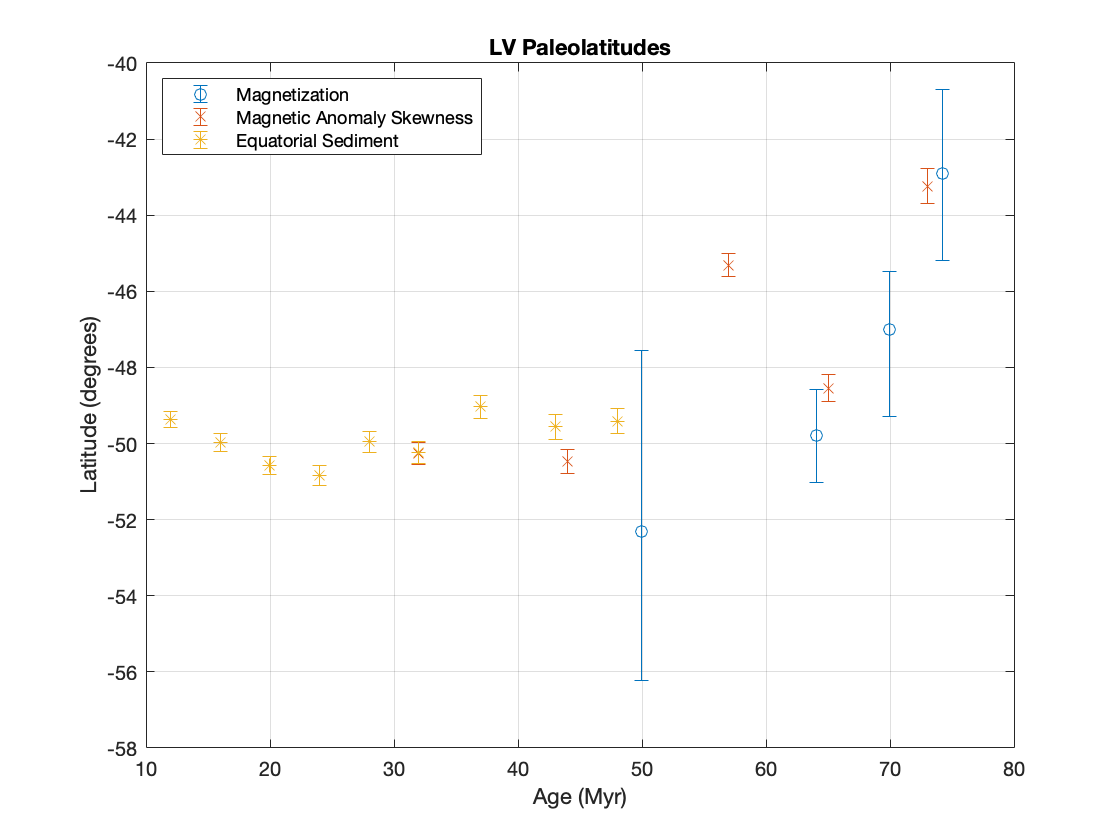

clear;
chain = "LV";
pole = importdata(strcat('P_lat/', chain, '_plat_poles.txt'));
spin = importdata(strcat('P_lat/', chain, '_plat_spin.txt'));
plat = importdata(strcat('P_lat/', chain, '_dist_age_plat.txt'));

age_pole = pole(:,4);
age_spin = spin(:,4);
age_plat = plat(:,4);

dist_pole = pole(:,3);
dist_spin = spin(:,3);
dist_plat = plat(:,3);

plat_pole = pole(:,5);
plat_spin = spin(:,5);
plat_plat = plat(:,5);

err_pole = pole(:,6);
err_spin = spin(:,6);
low_plat = (plat_plat - plat(:,7))./1.96;%convert to 1 sigma
high_plat = (plat(:,8) - plat_plat)./1.96;

figure(1);
errorbar(age_plat, plat_plat, low_plat, high_plat, 'o');
grid on; hold on;
errorbar(age_pole, plat_pole, err_pole, 'x');
errorbar(age_spin, plat_spin, err_spin, '*');
hold off;
title(strcat(chain,  " Paleolatitudes"));
xlabel('Age (Myr)');
ylabel('Latitude (degrees)');
legend('Magnetization', 'Magnetic Anomaly Skewness', 'Equatorial Sediment', 'Location', 'northwest');

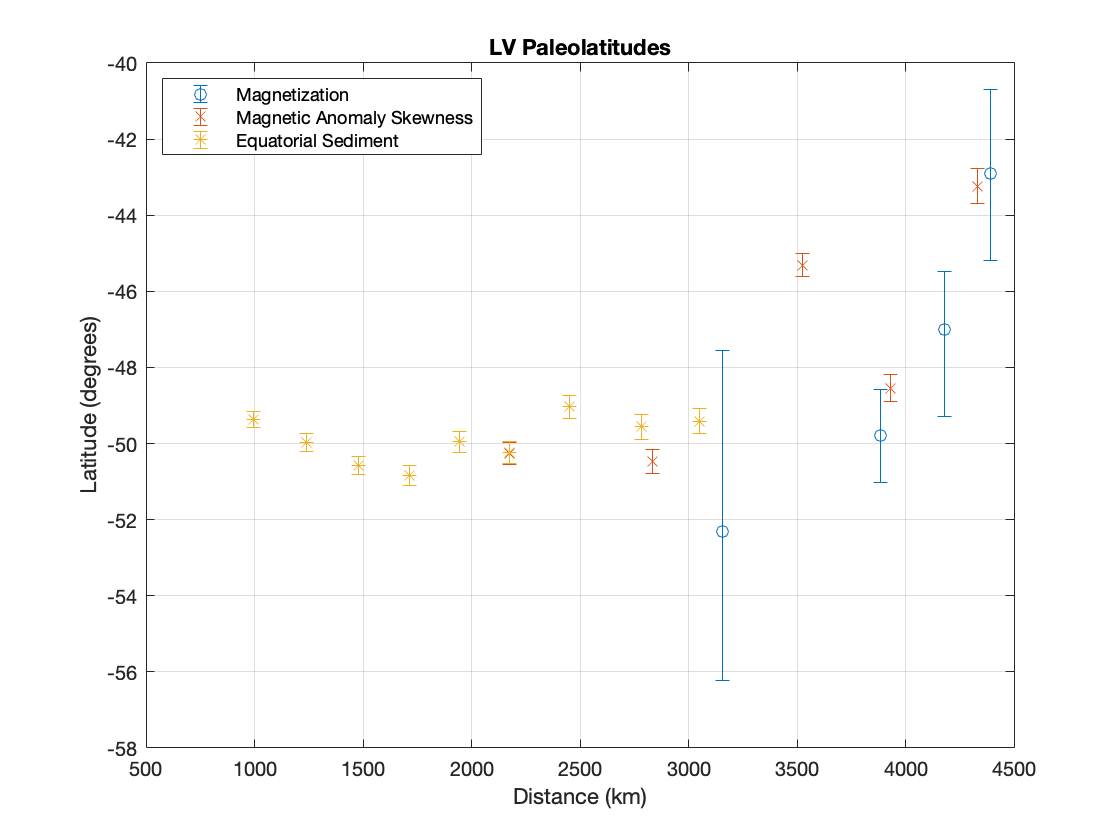

figure(2);
errorbar(dist_plat, plat_plat, low_plat, high_plat, 'o');
grid on; hold on;
errorbar(dist_pole, plat_pole, err_pole, 'x');
errorbar(dist_spin, plat_spin, err_spin, '*');
hold off;
title(strcat(chain, " Paleolatitudes"));
xlabel('Distance (km)');
ylabel('Latitude (degrees)');
legend('Magnetization', 'Magnetic Anomaly Skewness', 'Equatorial Sediment', 'Location', 'northwest');

## Hotspot data and error


age = importdata(strcat('final_line_width_age_tables/', chain, '_line_width_age.txt'));

HS_lon = interp1(age(:,12), age(:,1), 0,'spline') + 360

HS_lon = 221.0714

HS_lat = interp1(age(:,12), age(:,2), 0,'spline')

HS_lat = -50.6819

HS_azi_cross = interp1(age(:,12), age(:,4), 0,'spline');
HS_azi_along = interp1(age(:,12), age(:,4), 0,'spline') - 90;
HS_across = interp1(age(:,12), age(:,7), 0,'spline');
HS_along = interp1(age(:,12), age(:,15), 0,'spline');

%make sure larger axis is set as 'a' with corresponding azimuth
if HS_across < HS_along;
    a = HS_along;
    b = HS_across;
    theta = HS_azi_along;
else
    a = HS_across;
    b = HS_along;
    theta = HS_azi_cross;
end

% e will be imaginary if semi-major and minor axies are mixed up
e = sqrt(1 - (b/a)^2)

e = 0.9673

HS_err_dist = b/sqrt(1 - (e*cosd(theta))^2)

HS_err_dist = 64.7878

HS_err = HS_err_dist/(2*pi*6371.008771/360)

HS_err = 0.5826

## Non-weighted Polynomial Regression

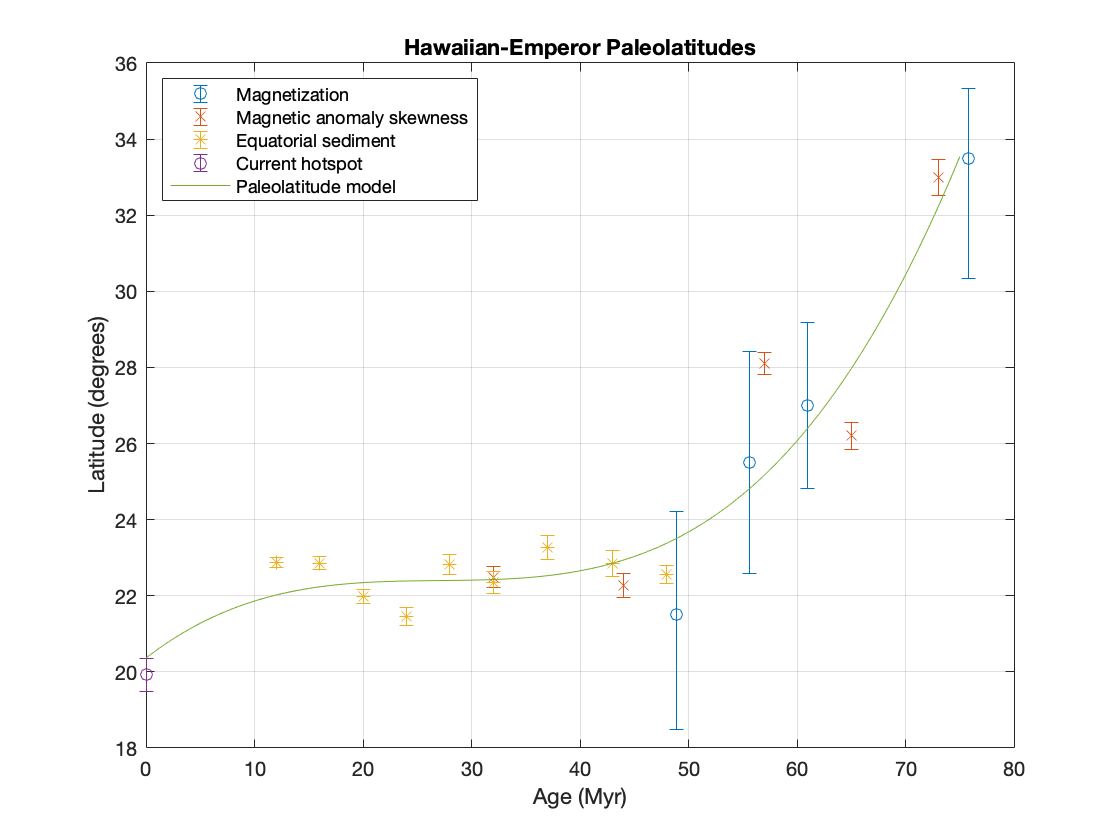

x = [0; age_plat; age_pole; age_spin];
y = [HS_lat; plat_plat; plat_pole; plat_spin];
n = length(x);
x_plot = 0:1:max(x);

A = [ones(n,1)];

%number of parameters = j+1
for j = 1:1:3;
    clear ym;
    A = [A, x.^j];
    coef = inv(A'*A)*A'*y;%unweighted
    ym = coef(1);
    for p = 2:1:j+1;
        ym = ym + coef(p).*x_plot.^(p-1);
    end
end

figure(3);
errorbar(age_plat, plat_plat, low_plat, high_plat, 'o');
grid on; hold on;
errorbar(age_pole, plat_pole, err_pole, 'x');
errorbar(age_spin, plat_spin, err_spin, '*');
errorbar(0,HS_lat, HS_err,'o');
plot(x_plot,ym);
hold off;
title('Hawaiian-Emperor Paleolatitudes');
xlabel('Age (Myr)');
ylabel('Latitude (degrees)');
legend('Magnetization', 'Magnetic anomaly skewness', 'Equatorial sediment','Current hotspot','Paleolatitude model', 'Location','northwest');

## F-Test

clear j p;
y_bar = mean(y);
alpha = 0.95;
q = 1;

%allocate storage
A1 = [ones(n,1)];
F = [];
F_crit = [];

for p = 1:1:5;
    %allocate storage for model values
    ym1 = 0;
    ym2 = 0;
    %find coefficents for p and p+q
    A1 = [A1,x.^p];
    A2 = [A1,x.^(p+q)];
    coef1 = inv(A1'*A1)*A1'*y; %unweighted
    coef2 = inv(A2'*A2)*A2'*y;
    %calculate model values
    for i = 0:1:p;
        ym1 = ym1 + coef1(i+1).*x.^i;
    end
    for j = 0:1:p+q;
        ym2 = ym2 + coef2(j+1).*x.^j;
    end
    %perform F-test using model values
    R_p = sum((ym1 - y_bar).^2)/sum((y - y_bar).^2);%unweighted
    R_p_q = sum((ym2 - y_bar).^2)/sum((y - y_bar).^2);
    ESS_p = R_p*100;
    ESS_p_q = R_p_q*100;
    F = [F, abs(((ESS_p_q - ESS_p)/q)/((100 - ESS_p_q)/(n - (p+1) - q - 1)))];
    F_crit = [F_crit, finv(alpha,q,n-q-(p+1)-1)];
    % get rid of model values for next iteration
    clear ym1;
    clear ym2;
end

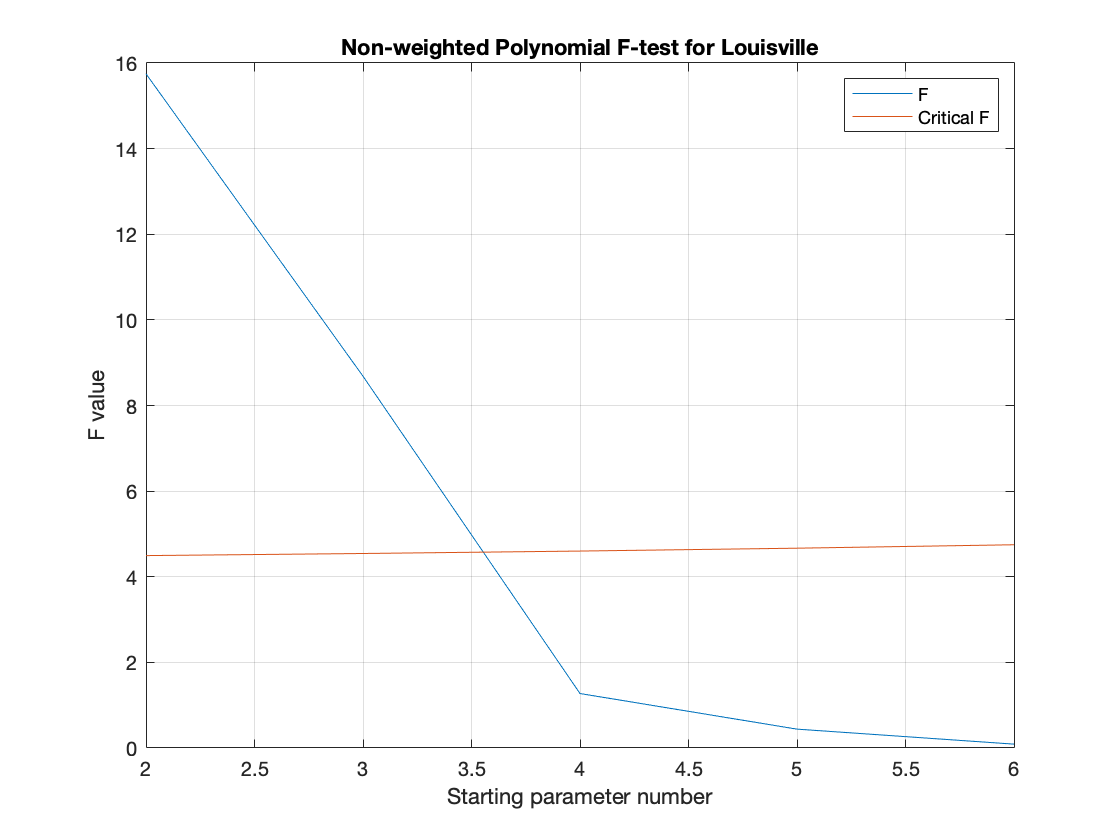


p_plot = 1:1:p;

figure(4);
plot(p_plot+1,F);
hold on; grid on;
plot(p_plot+1,F_crit);
title('Non-weighted Polynomial F-test for Louisville');
xlabel('Starting parameter number');
ylabel('F value');
legend('F','Critical F');
hold off;

## Weighted Regression

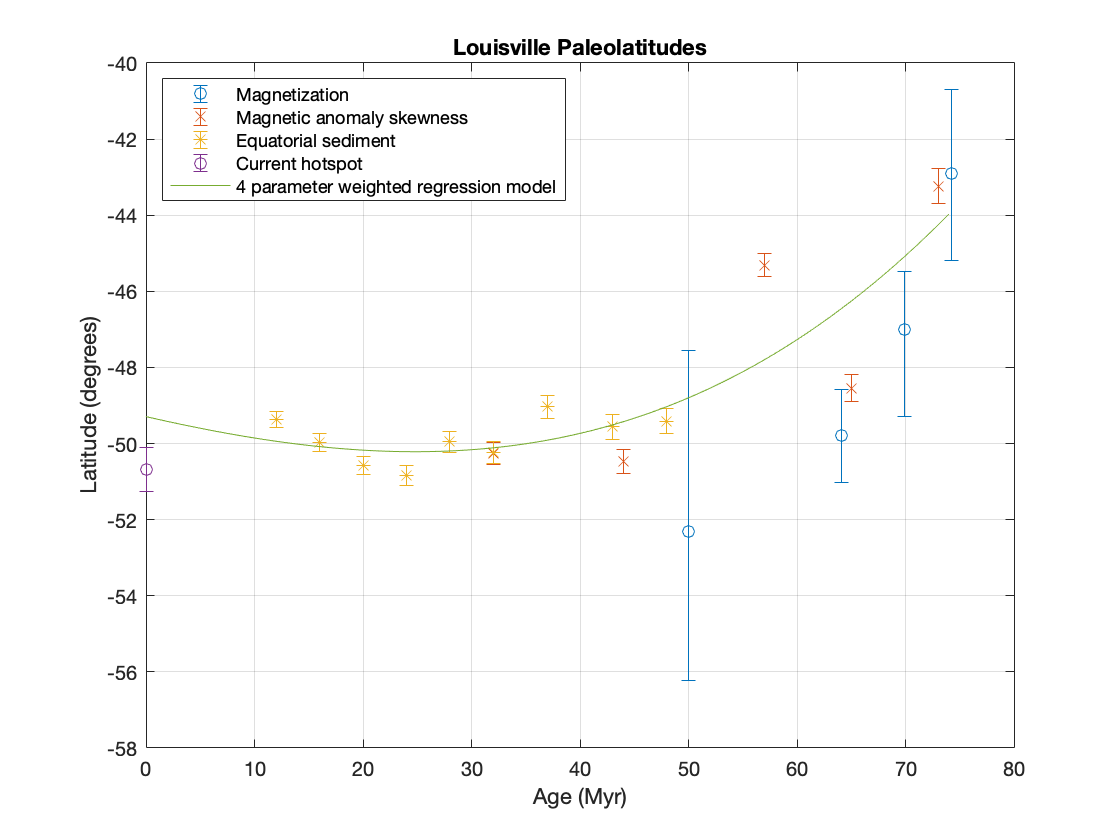

clear j p A;
x = [0; age_plat; age_pole; age_spin];
y = [HS_lat; plat_plat; plat_pole; plat_spin];
n = length(x);
x_plot = 0:1:max(x);

err_plat = (low_plat + high_plat)./2;
err = [HS_err; err_plat; err_pole; err_spin];

w = 1./err;%set weight as 1/error
w = w./sum(w);%make weights sum to 1
W = diag(w);%create the diagnal matrix of weights

A = [ones(n,1)];

%number of parameters = j+1
for j = 1:1:3;
    clear ym;
    A = [A, x.^j];
    coef = inv(A'*W'*W*A)*A'*W'*W*y; %weighted
    ym = coef(1);
    for p = 2:1:j+1;
        ym = ym + coef(p).*x_plot.^(p-1);
    end
end

figure(5);
errorbar(age_plat, plat_plat, low_plat, high_plat, 'o');
grid on; hold on;
errorbar(age_pole, plat_pole, err_pole, 'x');
errorbar(age_spin, plat_spin, err_spin, '*');
errorbar(0,HS_lat, HS_err,'o');
plot(x_plot,ym);
hold off;
title('Louisville Paleolatitudes');
xlabel('Age (Myr)');
ylabel('Latitude (degrees)');
legend('Magnetization', 'Magnetic anomaly skewness', 'Equatorial sediment','Current hotspot','4 parameter weighted regression model', 'Location','northwest');

## Weighted F-test

clear j p A1 A2;
y_bar = mean(y);

Unrecognized function or variable 'y'.

alpha = 0.95;
q = 1;
n_eff = (sum(w).^2)./sum(w.^2);

%allocate storage
A1 = [ones(n,1)];
F = [];
F_crit = [];

for p = 1:1:7;
    %allocate storage for model values
    ym1 = 0;
    ym2 = 0;
    %find coefficents for p and p+q
    A1 = [A1,x.^p];
    A2 = [A1,x.^(p+q)];
    coef1 = inv(A1'*W'*W*A1)*A1'*W'*W*y; %unweighted
    coef2 = inv(A2'*W'*W*A2)*A2'*W'*W*y;
    %calculate model values
    for i = 0:1:p;
        ym1 = ym1 + coef1(i+1).*x.^i;
    end
    for j = 0:1:p+q;
        ym2 = ym2 + coef2(j+1).*x.^j;
    end
    %perform F-test using model values
    R_p = sum(((ym1 - y_bar).*w).^2)/sum(((y - y_bar).*w).^2);%weighted
    R_p_q = sum(((ym2 - y_bar).*w).^2)/sum(((y - y_bar).*w).^2);
    ESS_p = R_p*100;
    ESS_p_q = R_p_q*100;
    F = [F, abs(((ESS_p_q - ESS_p)/q)/((100 - ESS_p_q)/(n_eff - (p+1) - q - 1)))];
    F_crit = [F_crit, finv(alpha,q,n_eff-q-(p+1)-1)];
    % get rid of model values for next iteration
    clear ym1;
    clear ym2;
end

p_plot = 1:1:p;

figure(4);
plot(p_plot+1,F);
hold on; grid on;
plot(p_plot+1,F_crit);
title('Weighted Polynomial F-test for Louisville');
xlabel('Starting parameter number');
ylabel('F value');
legend('F','Critical F');
hold off;

# Creating Data Table of all Paleo Data with Uncertainties 

%expoort as a text file
T = table(x, y, err)

T = 19×3 table
      x         y         err  
    _____    _______    _______

        0    -50.682    0.58265
    49.98      -52.3     4.3367
     64.1      -49.8     1.2245
    69.92        -47     1.9133
     74.2      -42.9     2.2449
       32     -50.26     0.2902
       44    -50.469     0.3232
       57    -45.309     0.3087
       65    -48.543     0.3558
       73    -43.241     0.4609
       12    -49.367     0.2032
       16    -49.976     0.2288
       20    -50.585     0.2404
       24    -50.837     0.2526
       28    -49.956       0.27
       32    -50.235     0.2897


writetable(T,strcat('P_lat/', chain, '_age_paleolat_err.txt'),'Delimiter','\t','WriteVariableNames',false);